 % clear ur;
 % ur = urRTDEClient('192.168.1.10','CobotName','universalUR5e')

% % Cargamos una pose de prueba
 testPose = rad2deg(readJointConfiguration(ur)');
 
% % Cargamos una foto de prueba a su vez
 [imgdata,img] = fotosw()

imgdata = 480×640×3 uint8 array
imgdata(:,:,1) =

   166   160   169   186   226   214   212   192   193   196   175   206   200   195   198   186   185   195   184   170   221   213   226   232   215   212   206   200   193   193   194   192   194   190   195   211   238   250   237   231   236   227   241   234   252   242   236   241   234   235   197   216   235   228   238   238   242   246   245   245   254   253   249   255   240   224   246   245   227   219   228   230   248   251   250   249   255   255   255   254   254   255   255   252   240   247   248   255   248   248   254   254   255   255   249   254   247   252   255   255   255   252   255   255   253   252   252   255   255   255   253   246   247   248   247   250   254   255   252   254   254   253   255   255   255   255   255   255   248   253   255   255   255   249   252   252   249   254   255   255   255   255   255   255   255   253   250   252   255   255   255   255   251   248   254   253   255   255  

img = "actualphoto.jpg"

 testImage = imgdata; 

% testPose = [88.8605 -62.3678 -78.9178 -128.9287 91.3690 -173.4337]'
% testImage = imread("actualPhoto.jpg")

undistortedTestImage = undistortImage(testImage,ld.cameraParams);

%Calculamos la transoformada de la base al efector final de la pose anterior
testPoseRad = deg2rad(testPose);
endEffectorToBaseTformTest = getTransform(robotModel,testPoseRad,"flange");

% Especificamos la familia a la que pertenece el AprilTag.
tagFamily = "tag36h11"; %<<<<<--------------------CAMBIAR ESTO
tagSize = .049; % AprilTag size in meters

% Detectamos el AprilTag en la imagen
[~,~,aprilTagToCameraTform] = readAprilTag(undistortedTestImage,"tag36h11",intrinsics,tagSize);

%Encontramos la transformada de la base del robot a la camara
cameraToBaseTestTform = rigidtform3d(endEffectorToBaseTformTest * cameraToEndEffectorTform.A);

%Encontramos la transformada de la base del robot al AprilTag
tagToBaseTestTform = cameraToBaseTestTform.A * aprilTagToCameraTform.A;
cubePosition = tagToBaseTestTform(1:3,4)

cubePosition =     0.1090
   -0.5111
   -0.0747


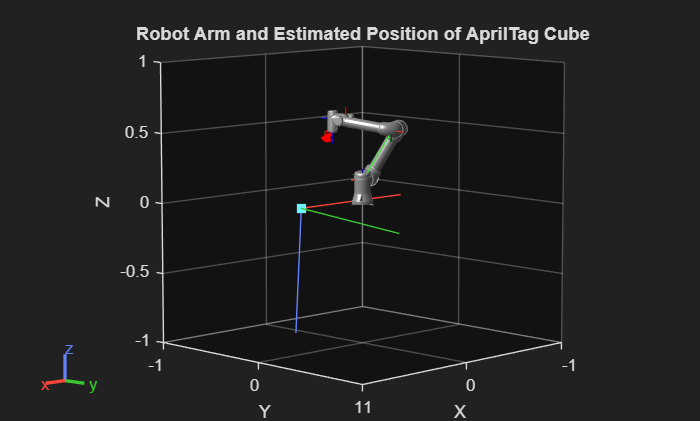

% Mostramos el modelo del robot
show(robotModel,testPoseRad);
hold on
rotate3d("on")
%Mostramos las posiciones estimadas y orientaciones de la camara y el cubo
plotCamera(AbsolutePose = cameraToBaseTestTform, Opacity=0, size=0.02)
scatter3(cubePosition(1), cubePosition(2), cubePosition(3), 50, 'square', 'filled')
cubeRotationQuaternion = rotm2quat(tagToBaseTestTform(1:3,1:3));
plotTransforms(cubePosition', cubeRotationQuaternion)
title("Robot Arm and Estimated Position of AprilTag Cube")
xlim([-1,1])
ylim([-1, 1])
zlim([-1,1])

jointAngles = readJointConfiguration(ur) %Lee los angulos del brazo

jointAngles =     2.0312   -1.0290   -1.9699   -1.7135    1.5708   -2.6820


coci = car2pol(cubePosition(1),cubePosition(2),cubePosition(3))

coci =     0.5226   -1.3606   -0.0747


jointAngles = MoverRobot(coci,-1.57,pi,jointAngles,ur);
pause(5)
jointAngles = readJointConfiguration(ur) %Lee los angulos del brazo

jointAngles =     2.0389   -2.0511   -2.0986   -0.5626    1.5708   -2.8845


coci = car2pol(0,-0.3,0.3)

coci =     0.3000   -1.5708    0.3000


jointAngles = MoverRobot(coci,-1.57,pi,jointAngles,ur);